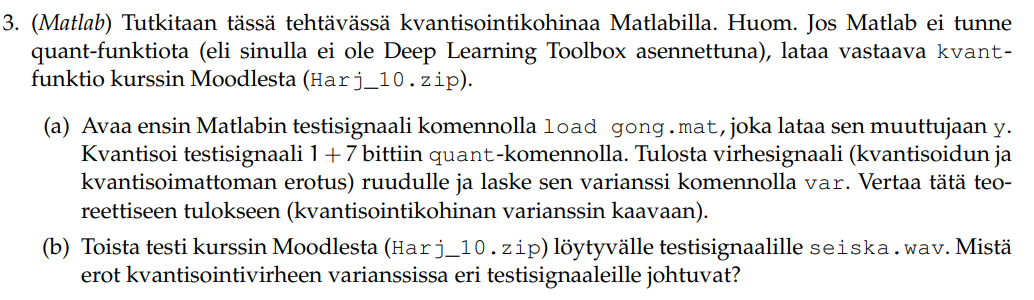


b=8-1

b = 7

%a
load gong.mat
e = quant(y,2^-b);
v=y-e;
var(v)

ans = 4.9376e-06

teoreettinen=2^(-2*b)/12

teoreettinen = 5.0863e-06

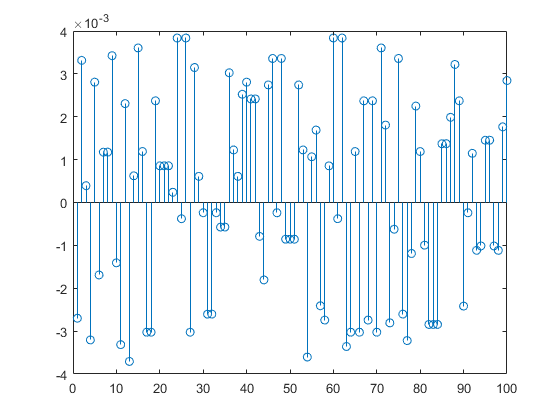

%teoreettinen = 5.0863e-06
stem(v(1:100))

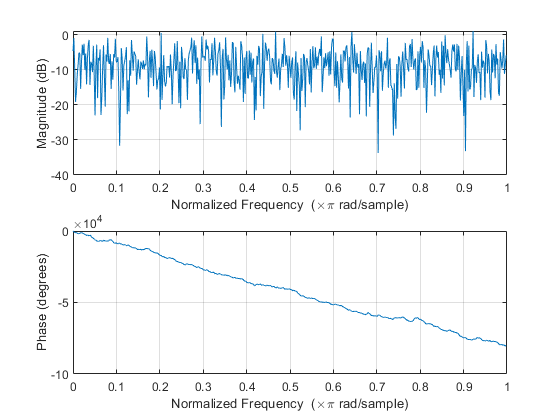

freqz(v)

%b
[x, Fs]=audioread("seiska.wav");
e = quant(x,2^-b);
v=x-e;
var(v)

ans = 4.9838e-06

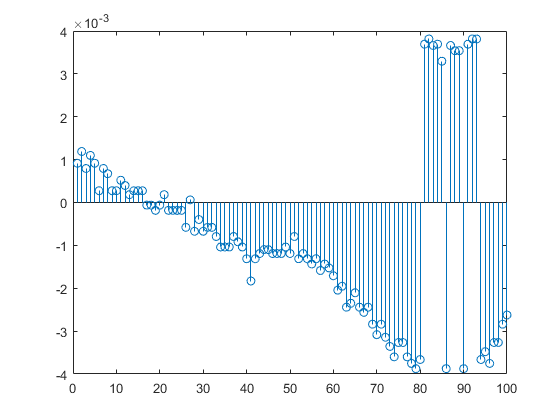

stem(v(1:100))

%teoreettinen = 5.0863e-06

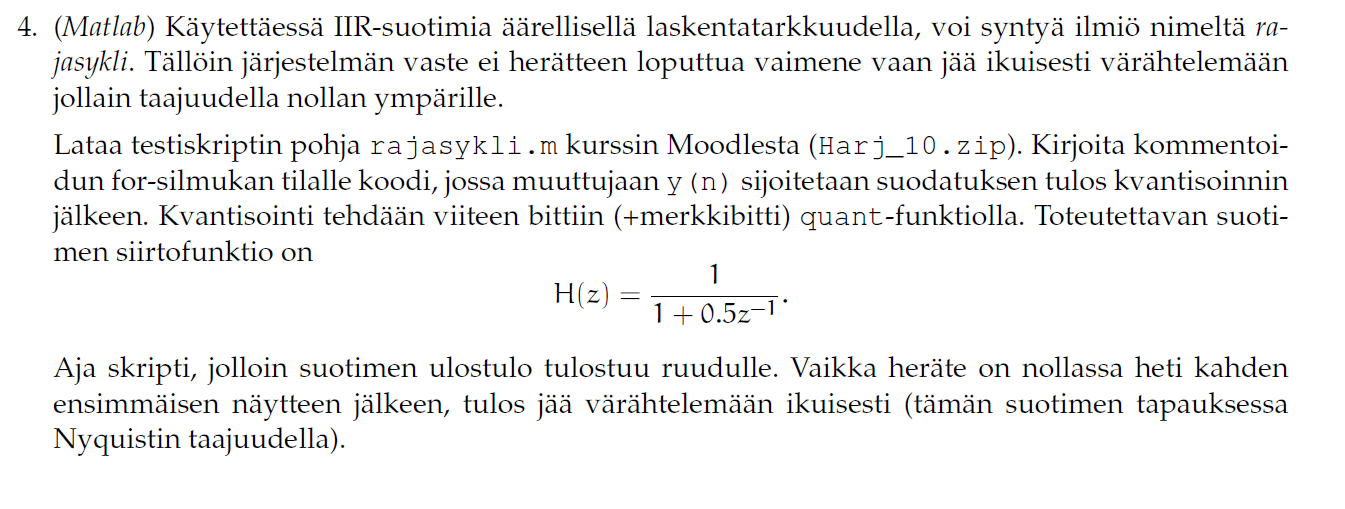

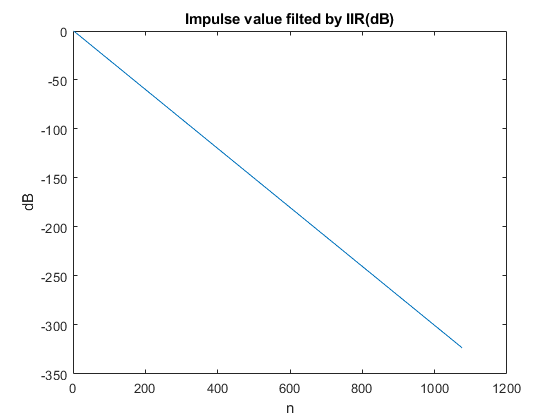

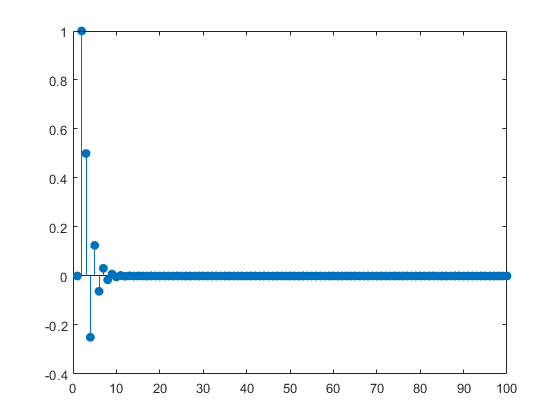


% N = 10000; % Testisignaalin pituus
% x = [1; 1; zeros(N,1)]; % Syöte
% y = zeros(size(x)); % Vaste
% 
% % Kirjoita alle y(n):ään suodatuksen tulos kvantisoinnin
% % jälkeen, kun suodin on H(z) = 1 / (1 + 0.5z^(-1)).
% 
% for n = 2:N
%     y(n) = -0.5*y(n-1)+x(n-1);
% end
% 
% %tai ei käytetä for, vaan filteri
% %b = 1;
% %a = [1 ,0.5];
% %x_kvant = quant(x,2^-5);
% %y = filter(b,a,x_kvant);跟for 循环相同
%     
% stem(y(1:100), 'filled')
% figure
% plot(1:length(y),log10(y))
% title('Impulse value filted by IIR(dB)')
% xlabel('n') 
% ylabel('dB') 
% 
% soundsc(y,8000)

clear all
rajasykli

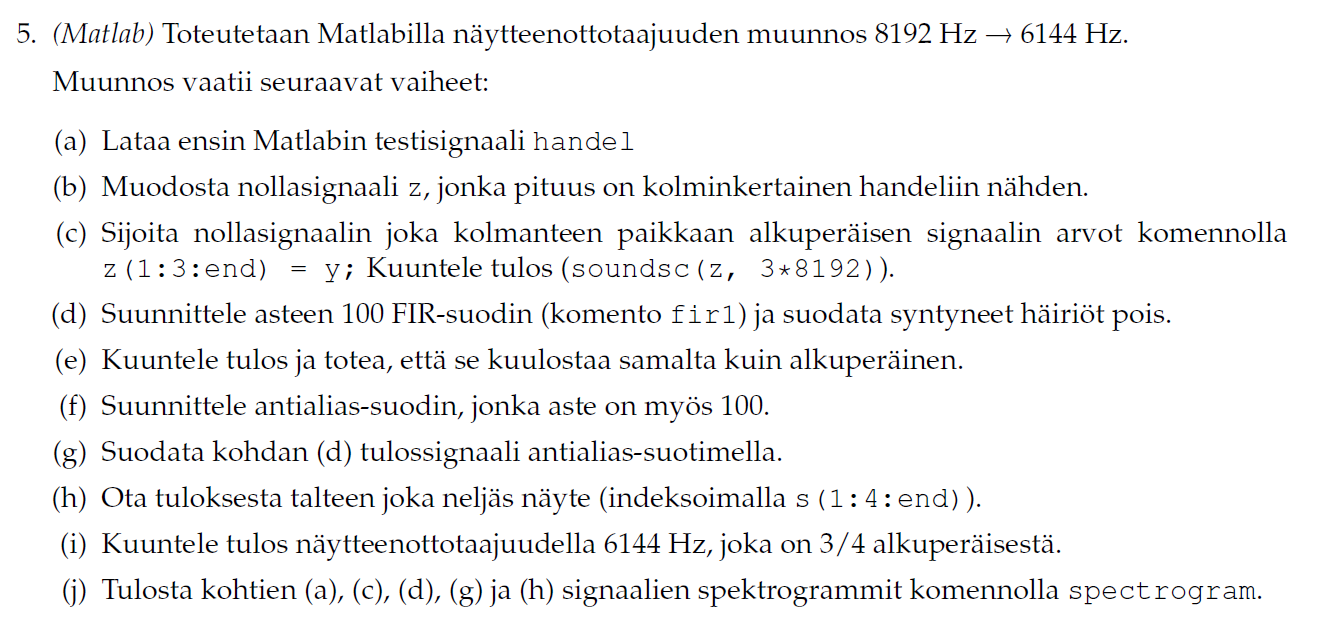

clear all
%6144Hz*3/4=8192Hz
L = 3

L = 3

M = 4

M = 4

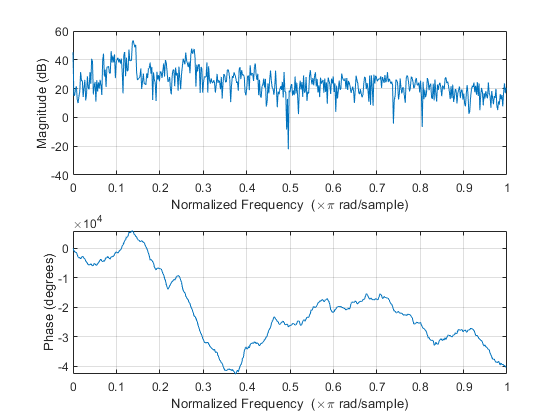

%a
clear all
load handel.mat
freqz(y)

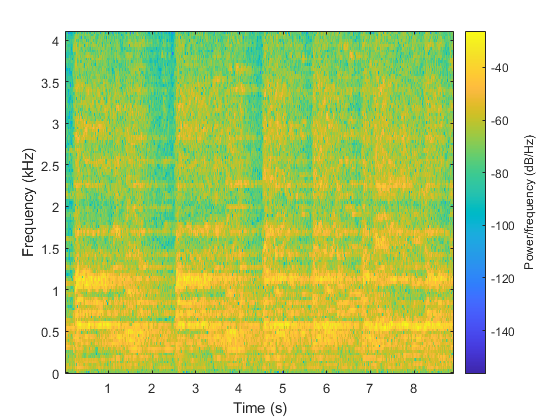

spectrogram(y,256,[],[],Fs,'yaxis')


%b
Length=length(y);
z=zeros(1,3*Length);

%c
z(1:3:end)=y

z =          0         0         0   -0.0062         0         0   -0.0750         0         0   -0.0312         0         0    0.0062         0         0    0.0381         0         0    0.0189         0         0   -0.0250         0         0   -0.0312         0         0   -0.0750         0         0   -0.1258         0         0   -0.1443         0         0   -0.1812         0         0   -0.1905         0         0   -0.0750         0         0   -0.0127         0         0   -0.0381         0


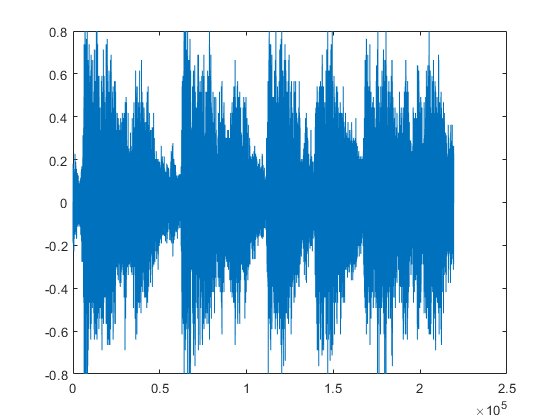

%soundsc(z,3*Fs)
plot(0:3*Length-1,z);%% 这一步操作类似于箭头上的L，之后Näyteenottotaajuus都要乘三

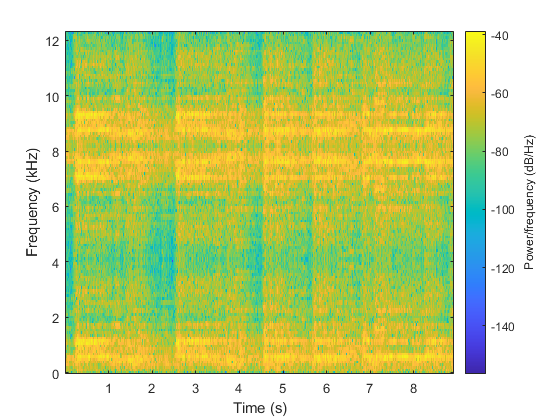

spectrogram(z,256,[],[],3*Fs,'yaxis')


%d
%intepolointia ensi
%oletetaan siirtymäkaista on 0
N = 101;
fc = 1/6;%1/(2*L)
d = fir1(N-1,fc*2,'low')

d =     0.0004    0.0005   -0.0000   -0.0005   -0.0006    0.0000    0.0007    0.0008   -0.0000   -0.0010   -0.0012   -0.0000    0.0015    0.0017   -0.0000   -0.0021   -0.0024    0.0000    0.0030    0.0033   -0.0000   -0.0040   -0.0045    0.0000    0.0054    0.0059   -0.0000   -0.0072   -0.0078    0.0000    0.0094    0.0103   -0.0000   -0.0123   -0.0135    0.0000    0.0164    0.0181   -0.0000   -0.0224   -0.0251    0.0000    0.0325    0.0376   -0.0000   -0.0538   -0.0679    0.0000    0.1372    0.2752


%filted=3*filter(d,1,z)
filted=3*conv(d,z)                   %pitää kertaa 'L' jotta signaalin energia säilyy

filted =          0         0         0   -0.0000   -0.0000    0.0000   -0.0001   -0.0001    0.0000    0.0001    0.0001   -0.0000   -0.0001   -0.0001    0.0000    0.0002    0.0002    0.0000   -0.0002   -0.0002    0.0000    0.0003    0.0003   -0.0000   -0.0004   -0.0005   -0.0000    0.0005    0.0006   -0.0000   -0.0009   -0.0009    0.0000    0.0009    0.0010   -0.0000   -0.0014   -0.0016    0.0000    0.0016    0.0018   -0.0000   -0.0023   -0.0025   -0.0000    0.0031    0.0034   -0.0000   -0.0045   -0.0051


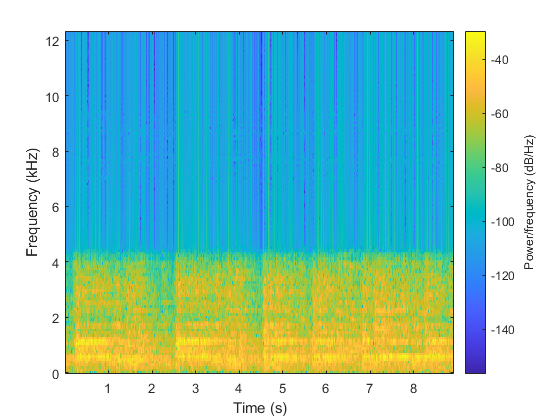

spectrogram(filted,256,[],[],3*Fs,'yaxis')


%e
%soundsc(filted,3*Fs)

%f
fc2 = 1/8;%1/(2*M)
d2=fir1(N-1,fc2*2,'low')

d2 =     0.0005    0.0004   -0.0000   -0.0004   -0.0007   -0.0005    0.0000    0.0006    0.0010    0.0008   -0.0000   -0.0011   -0.0017   -0.0014    0.0000    0.0017    0.0027    0.0022   -0.0000   -0.0027   -0.0042   -0.0033    0.0000    0.0040    0.0063    0.0049   -0.0000   -0.0058   -0.0091   -0.0070    0.0000    0.0084    0.0130    0.0101   -0.0000   -0.0122   -0.0189   -0.0148    0.0000    0.0183    0.0290    0.0232   -0.0000   -0.0307   -0.0513   -0.0440    0.0000    0.0744    0.1585    0.2248



%g
filted2=filter(d2,1,filted)

filted2 =          0         0         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000


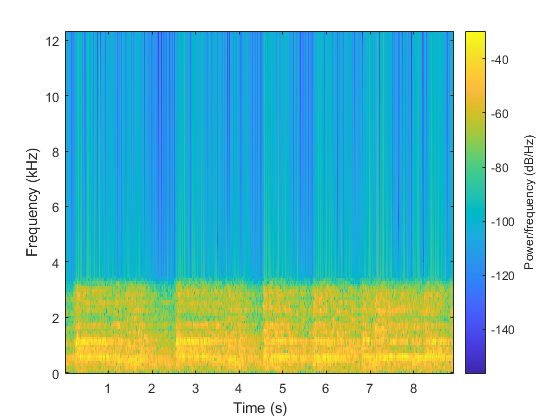

%soundsc(filted2,3*Fs)
spectrogram(filted2,256,[],[],3*Fs,'yaxis')


%h
s=filted2(1:4:end)                %% 这一步操作类似于箭头下的M,之后Näyteenottotaajuus都要除四

s =          0   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0001    0.0001   -0.0001    0.0003   -0.0004    0.0006   -0.0010    0.0013   -0.0021    0.0029   -0.0046    0.0079   -0.0356   -0.0562    0.0124    0.0351   -0.0106   -0.0346   -0.0935   -0.1392   -0.1821   -0.1608   -0.0159   -0.0462   -0.0538    0.0505    0.1316    0.1744    0.1316    0.0861    0.0393   -0.0440   -0.0904   -0.0242   -0.0085   -0.0742


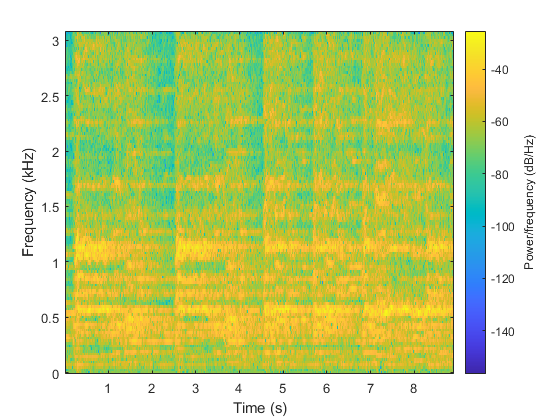

spectrogram(s,256,[],[],3*Fs/4,'yaxis')


%i
%soundsc(s,3*Fs/4)







